[x, y, u, u_exact] = importfile("results_poisson.dat");

length(x)

ans = 10000

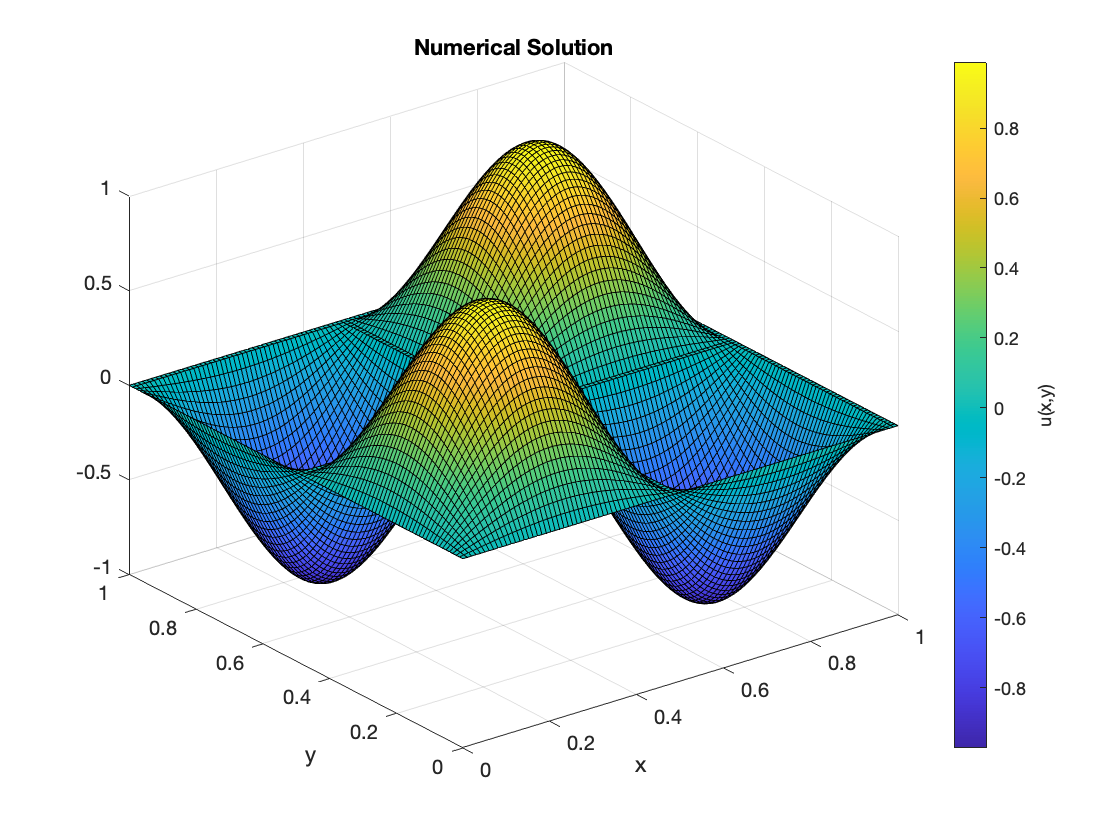

%resize data into a 2D array
N = sqrt(length(x));
u_array = reshape(u,N,N);
u_exact_array = reshape(u_exact,N,N);
X = reshape(x,N,N);
Y = reshape(y,N,N);

%surf(X,Y,u_array, 'edgecolor','none')
surf(X,Y,u_array)
xlabel('x');
ylabel('y');
c = colorbar;
c.Label.String = 'u(x,y)';
title('Numerical Solution')

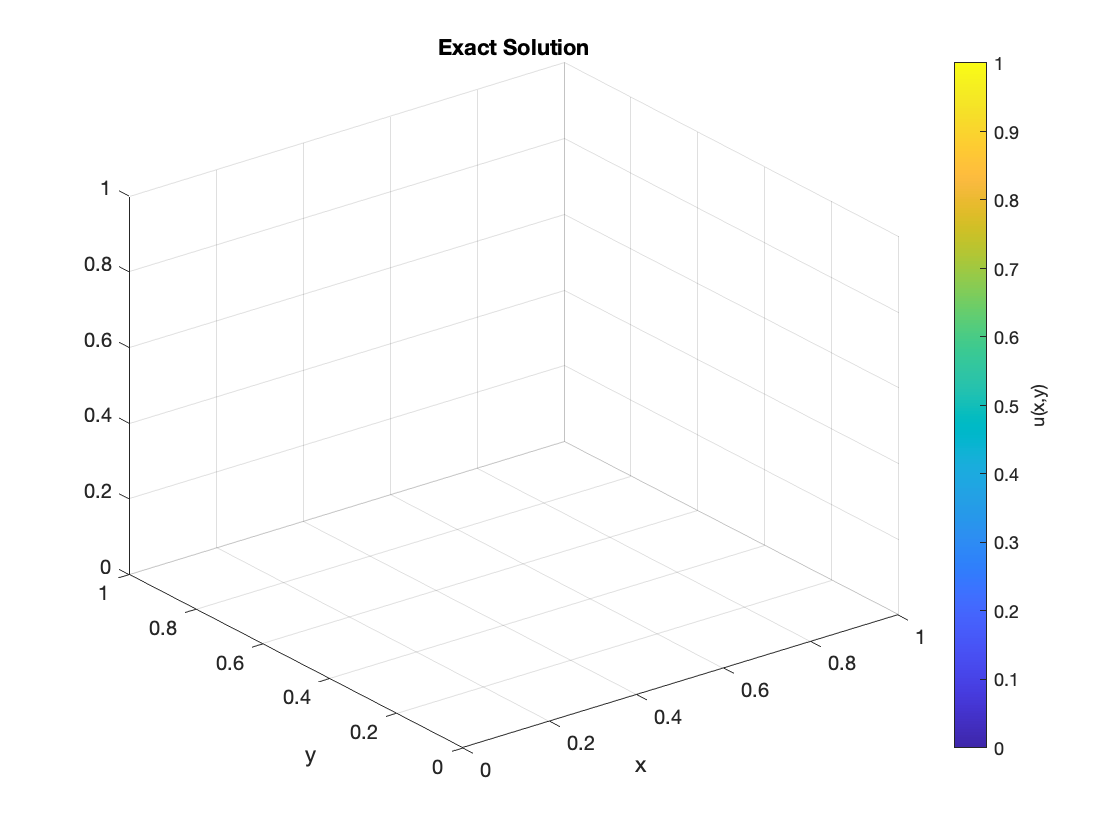


surf(X,Y,u_exact_array)
xlabel('x');
ylabel('y');
c = colorbar;
c.Label.String = 'u(x,y)';
title('Exact Solution')

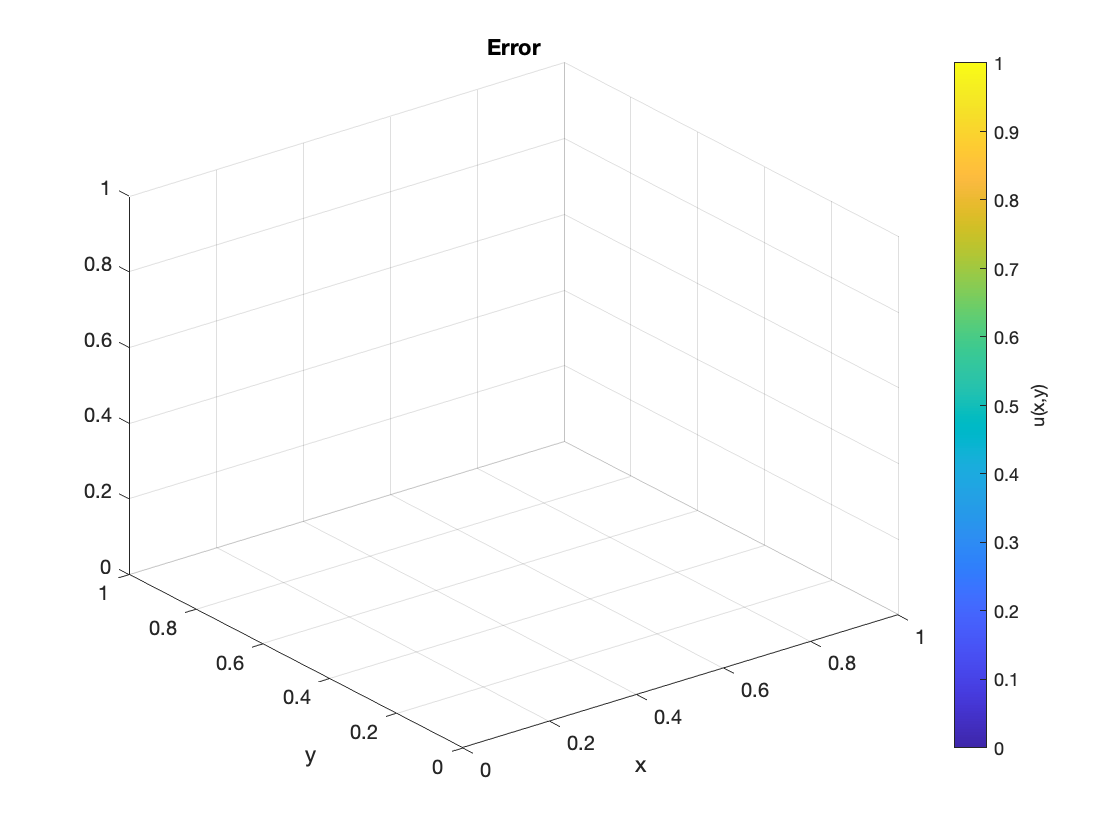



surf(X,Y,u_array-u_exact_array)
xlabel('x');
ylabel('y');
c = colorbar;
c.Label.String = 'u(x,y)';
title('Error')